clear 
clc

fileID = fopen('degree_13');
data = fread(fileID,'single') 

data = 1.0e+08 *

   -0.0991
   -0.1003
   -0.0974
   -0.0970
   -0.1019
   -0.1007
   -0.1032
   -0.1011
   -0.0986
   -0.0999


%data = data/max(data)*2; 
data = data/power(2,31);
fs = 41.6667e3;
numMics = 8;
numSamples = 190;
onePacketLength = numSamples*numMics 

onePacketLength = 1520

numPacketsInData = floor(length(data)/onePacketLength)

numPacketsInData = 3071

splitdata = zeros(numSamples,numMics);
for i = 0:numPacketsInData-1
    splitdata = [splitdata; reshape(data(i*onePacketLength+1:(i+1)*onePacketLength),[],numMics)];
end
splitdata = splitdata(numSamples+1:end,:)'

splitdata =    -0.0046   -0.0047   -0.0045   -0.0045   -0.0047   -0.0047   -0.0048   -0.0047   -0.0046   -0.0047   -0.0049   -0.0047   -0.0048   -0.0047   -0.0047   -0.0046   -0.0047   -0.0046   -0.0045   -0.0046   -0.0047   -0.0049   -0.0046   -0.0045   -0.0047   -0.0047   -0.0044   -0.0044   -0.0042   -0.0044   -0.0045   -0.0044   -0.0045   -0.0046   -0.0044   -0.0043   -0.0045   -0.0044   -0.0044   -0.0046   -0.0045   -0.0045   -0.0046   -0.0045   -0.0045   -0.0046   -0.0045   -0.0045   -0.0046   -0.0044
    0.0045    0.0042    0.0044    0.0044    0.0043    0.0043    0.0042    0.0039    0.0044    0.0044    0.0042    0.0045    0.0042    0.0047    0.0043    0.0042    0.0045    0.0039    0.0045    0.0043    0.0040    0.0042    0.0041    0.0039    0.0041    0.0041    0.0042    0.0041    0.0040    0.0039    0.0042    0.0042    0.0042    0.0041    0.0040    0.0044    0.0044    0.0044    0.0043    0.0040    0.0042    0.0042    0.0039    0.0041    0.0044    0.0042    0.0046    0.0042    0.0

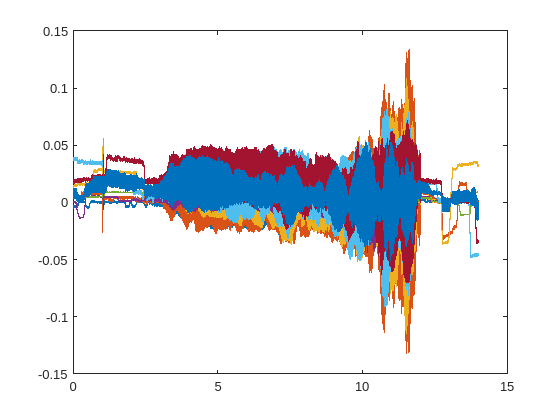


t = (0:1/fs:(length(splitdata)-1)/fs);
plot(t,splitdata(:,:))
hold on
%xlim([5 5.5])
%ylim([-0.2 0.2])
hold off


%sound(splitdata(8,:),41e3)

% [p_mic0, f_mic0] = pspectrum(splitdata(1,:),fs);
% [p_mic1, f_mic1] = pspectrum(splitdata(2,:),fs);
% [p_mic2, f_mic2] = pspectrum(splitdata(3,:),fs);
% [p_mic3, f_mic3] = pspectrum(splitdata(4,:),fs);
% [p_mic4, f_mic4] = pspectrum(splitdata(5,:),fs);
% [p_mic5, f_mic5] = pspectrum(splitdata(6,:),fs);
% [p_mic6, f_mic6] = pspectrum(splitdata(7,:),fs);
% [p_fir, f_fir] = pspectrum(splitdata(8,:),fs);
% 
% %plot(f_mic0,10*log10(p_mic0))
% %hold on
% %plot(f_mic3,10*log10(p_mic3))
% %plot(f_mic6,10*log10(p_mic6))
% plot(f_mic6,10*log10((p_mic0 + p_mic1 + p_mic2 + p_mic3 + p_mic4 + p_mic5 + p_mic6)*1/7))
% hold on
% %plot(f_mic0,10*log10(p_mic0))
% plot(f_fir,10*log10(p_fir))
% legend('Before filter', 'After filter')
% %legend('Mic 0', 'Mic 3', 'Mic 6', 'Output of FIR1')
% xlim([0 fs/2])
% grid minor
% hold off

